% Code to read the output data file from the Simulink recorder
% Imperial College London
% Flight Sim Lab 18/02/2025
% Author Himmat Kaul

## read data

clear; clc; close all;

format long
s = settings;
s.matlab.fonts.editor.code.Name.TemporaryValue = 'Calibri';
set(groot,'defaultLineLineWidth',2)  %sets graph line width as 2
set(groot,'defaultAxesFontSize',24)  %sets graph axes font size as 18
set(groot,'defaulttextfontsize',24)  %sets graph text font size as 18
set(groot,'defaultLineMarkerSize',14) %sets line marker size as 8
set(groot,'defaultAxesXGrid','on')   %sets X axis grid on
set(groot,'defaultAxesYGrid','on')   %sets Y axis grid on
set(groot,'DefaultAxesBox', 'on')   %sets Axes boxes on

picturewidth = 30; % set this parameter and keep it forever
hw_ratio = 0.65; % feel free to play with this ratio

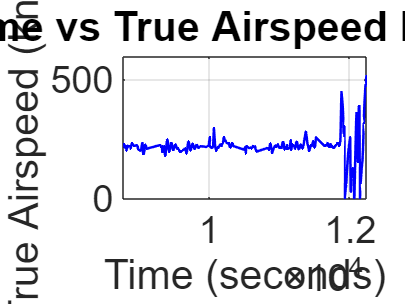

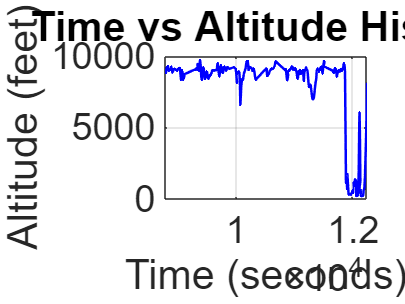

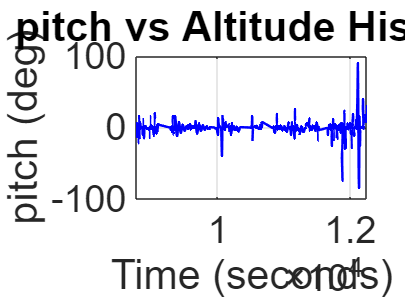

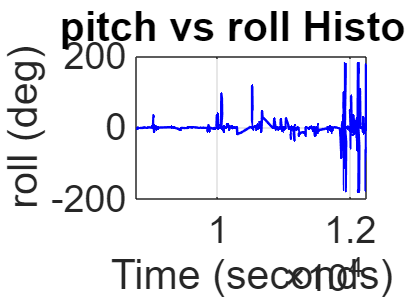

%%%%%INSERT THE FILENAME HERE%%%%%
fname = "Himmat Code First Lab\FlightDynLabPt1_2025-02-17_10-45-14.mat"; % Update to match the provided file
load(fname) % Load the .mat file

% Check if the loaded data structure exists and extract appropriately
if exist('data', 'var')
    % && isfield(data, 'Data') && ~isempty(data.Data)
    % Extract all the data
    vInd_kias   = data.Data(:,1); % Indicated Airspeed - Knots
    vTrue_ktas  = data.Data(:,2); % True Airspeed      - Knots
    climb_rate  = data.Data(:,3); % Climb rate         - fpm
    q           = data.Data(:,7); % Pitch rate         - rad/s
    p           = data.Data(:,8); % Roll rate          - rad/s
    r           = data.Data(:,9); % Yaw rate           - rad/s
    pitch       = data.Data(:,10);% Pitch angle        - deg
    roll        = data.Data(:,11);% Roll angle         - deg
    heading_true= data.Data(:,12);% Heading            - deg
    alpha       = data.Data(:,13);% Angle of Attack    - deg
    beta        = data.Data(:,14);% Side slip angle    - deg
    latitude    = data.Data(:,15);% Latitude           - deg
    longitude   = data.Data(:,16);% Longitude          - deg
    altitude    = data.Data(:,17);% Altitude           - ft
    x           = data.Data(:,18);
    y           = data.Data(:,19);
    z           = data.Data(:,20);
    throttle_cmd = data.Data(:,21);% Throttle command  - %
    throttle_actual = data.Data(:,22);
    eng_power   = data.Data(:,23); % Engine power      - hp
    w_empty     = data.Data(:,24);
    w_payld     = data.Data(:,25); % Payload weight    - lb
    w_fuel      = data.Data(:,26); % Fuel weight       - lb
    time        = data.Data(:,27); % Time from start   - seconds
    elevator    = data.Data(:,28); % Tail incidence    - %
    aileron     = data.Data(:,29); %                  - %
    rudder      = data.Data(:,30); %                  - %

    % Plot Time vs True Airspeed to verify results present
    figure;
    plot(time, vTrue_ktas, 'b', 'LineWidth', 1.5)
    xlabel('Time (seconds)')
    ylabel('True Airspeed (knots)')
    title('Time vs True Airspeed History')
    grid on;

    figure;
    plot(time, altitude, 'b', 'LineWidth', 1.5)
    xlabel('Time (seconds)')
    ylabel('Altitude (feet)')
    title('Time vs Altitude History')
    grid on;

    figure;
    plot(time, pitch, 'b', 'LineWidth', 1.5)
    xlabel('Time (seconds)')
    ylabel('pitch (deg)')
    title('pitch vs Altitude History')
    grid on;

    figure;
    plot(time, roll, 'b', 'LineWidth', 1.5)
    xlabel('Time (seconds)')
    ylabel('roll (deg)')
    title('pitch vs roll History')
    grid on;


else
    error('The loaded file does not contain the expected data structure.')
end

% convert values to SI units

vInd_kias   = vInd_kias * 0.514444; % Indicated Airspeed - m/s
vTrue_ktas  = vTrue_ktas * 0.514444; % True Airspeed      - m/s
climb_rate  = climb_rate * 0.00508; % Climb rate         - fpm
% q           = data.Data(:,7); % Pitch rate         - rad/s
% p           = data.Data(:,8); % Roll rate          - rad/s
% r           = data.Data(:,9); % Yaw rate           - rad/s
pitch       = deg2rad(pitch);% Pitch angle        - rad
roll        = deg2rad(roll);% Roll angle         - rad
heading_true= deg2rad(heading_true);% Heading            - rad
alpha       = deg2rad(alpha);% Angle of Attack    - rad
beta        = deg2rad(beta);% Side slip angle    - rad
latitude    = deg2rad(latitude);% Latitude           - rad
longitude   = deg2rad(longitude);% Longitude          - rad
altitude    = altitude * 0.3048;% Altitude           - m
% x           = data.Data(:,18);
% y           = data.Data(:,19);
% z           = data.Data(:,20);
% throttle_cmd = data.Data(:,21);% Throttle command  - %
% throttle_actual = data.Data(:,22);
eng_power   = eng_power * 745.7; % Engine power      - W
w_empty     = w_empty * 0.453592;
w_payld     = w_payld * 0.453592; % Payload weight    - kg
w_fuel      = w_fuel * 0.453592; % Fuel weight       - kg
% time        = data.Data(:,27); % Time from start   - seconds
% elevator    = data.Data(:,28); % Tail incidence    - %
% aileron     = data.Data(:,29); %                  - %
% rudder      = data.Data(:,30); %                  - %

## Testing Functions

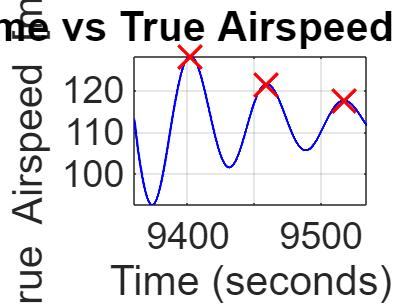

% idx1 = find(time == 11341)
% idx2 = find(time == 11451.1,'nearest')

[ ~, idx1 ] = min( abs( time-9359.83 ) );
[ ~, idx2 ] = min( abs( time-9534.34 ) );



V_test = vTrue_ktas(idx1:idx2);
t_test = time(idx1:idx2);

% Test Figure
figure;
plot(t_test, V_test, 'b', 'LineWidth', 1.5)
hold on
% finds Peaks
[~,id] = findpeaks(V_test, 'MinPeakDistance', 20);
% displays peaks
plot(t_test(id), V_test(id), 'rx',MarkerSize=20)
xlabel('Time (seconds)')
ylabel('True Airspeed [ms^-1]')
title('Time vs True Airspeed History')
grid on;
hold off



[omega_damped, damping_ratio, omega_natural, lambda_1, lambda_2] = periodic_response(t_test, V_test);

%lambda = non_periodic_response(t_test, V_test);
%
% [mean_lambda, lambda] = non_periodic_response(time, vTrue_ktas)

## SPPO (ossilitory)

characterised by pitch

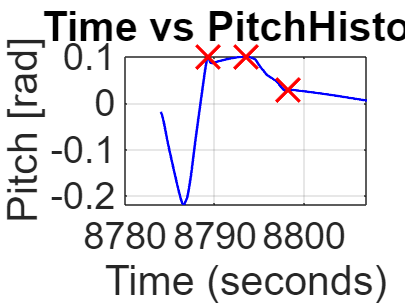

% test 1
[ ~, idx1 ] = min( abs( time-8784 ) );
[ ~, idx2 ] = min( abs( time-8807 ) );

Pitch_SPPO_1 = pitch(idx1:idx2);
t_SPPO_1 = time(idx1:idx2);

 figure;
 plot(t_SPPO_1, Pitch_SPPO_1, 'b', 'LineWidth', 1.5);
 hold on
%find Peaks
 [~,id] = findpeaks(Pitch_SPPO_1, 'MinPeakDistance', 5);
 %displays peaks
 plot(t_SPPO_1(id), Pitch_SPPO_1(id), 'rx',MarkerSize=20)
 xlabel('Time (seconds)')
 ylabel('Pitch [rad]')
 title('Time vs PitchHistory')
 grid on;
 hold off



%SPPO_1 = periodic_response(t_SPPO_1, Pitch_SPPO_1);
%SPPO_1_lambda = non_periodic_response(t_SPPO_1, Pitch_SPPO_1);


%[SPPO_1_DR, SPPO_1_dampedFreq,SPPO_1_undampedFreq,SPPO_1_eig1,SPPO_1_eig2] = getEigens(t_SPPO_1, Pitch_SPPO_1)

## test 2

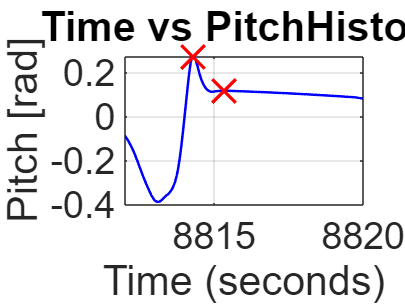

[ ~, idx1 ] = min( abs( time-8812 ) );
[ ~, idx2 ] = min( abs( time-8820 ) );

Pitch_SPPO_2 = pitch(idx1:idx2);
t_SPPO_2 = time(idx1:idx2);

%figure;
plot(t_SPPO_2, Pitch_SPPO_2, 'b', 'LineWidth', 1.5)
hold on
% finds Peaks
[~,id] = findpeaks(Pitch_SPPO_2, 'MinPeakDistance', 5);
% displays peaks
plot(t_SPPO_2(id), Pitch_SPPO_2(id), 'rx',MarkerSize=20)
xlabel('Time (seconds)')
ylabel('Pitch [rad]')
title('Time vs PitchHistory')
grid on;
hold off



%SPPO_2 = periodic_response(t_SPPO_2, Pitch_SPPO_2);
%SPPO_2_lambda = non_periodic_response(t_SPPO_2, Pitch_SPPO_2);


%[SPPO_2_DR, SPPO_2_dampedFreq,SPPO_2_undampedFreq,SPPO_2_eig1,SPPO_2_eig2] = getEigens(t_SPPO_2, Pitch_SPPO_2)

## test 3

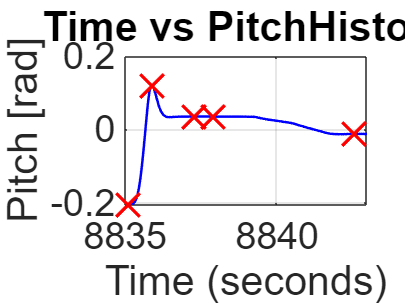

[ ~, idx1 ] = min( abs( time-8835 ) );
[ ~, idx2 ] = min( abs( time-8843 ) );

Pitch_SPPO_3 = pitch(idx1:idx2);
t_SPPO_3 = time(idx1:idx2);

figure;
plot(t_SPPO_3, Pitch_SPPO_3, 'b', 'LineWidth', 1.5)
hold on
% finds Peaks
[~,id] = findpeaks(Pitch_SPPO_3, 'MinPeakDistance', 5);
% displays peaks
plot(t_SPPO_3(id), Pitch_SPPO_3(id), 'rx',MarkerSize=20)
xlabel('Time (seconds)')
ylabel('Pitch [rad]')
title('Time vs PitchHistory')
grid on;
hold off



%SPPO_3 = periodic_response(t_SPPO_3, Pitch_SPPO_3);
 %SPPO_3_lambda = non_periodic_response(t_SPPO_3, Pitch_SPPO_3);

## test 4

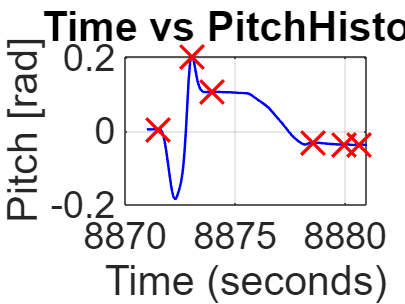

[ ~, idx1 ] = min( abs( time-8871 ) );
[ ~, idx2 ] = min( abs( time-8881 ) );

Pitch_SPPO_4 = pitch(idx1:idx2);
t_SPPO_4 = time(idx1:idx2);

figure;
plot(t_SPPO_4, Pitch_SPPO_4, 'b', 'LineWidth', 1.5)
hold on
% finds Peaks
[~,id] = findpeaks(Pitch_SPPO_4, 'MinPeakDistance', 5);
% displays peaks
plot(t_SPPO_4(id), Pitch_SPPO_4(id), 'rx',MarkerSize=20)
xlabel('Time (seconds)')
ylabel('Pitch [rad]')
title('Time vs PitchHistory')
grid on;
hold off



%SPPO_4 = periodic_response(t_SPPO_4, Pitch_SPPO_4);
%SPPO_4_lambda = non_periodic_response(t_SPPO_4, Pitch_SPPO_4);
% define data series

## test 5

[ ~, idx1 ] = min( abs( time-11720 ) );
[ ~, idx2 ] = min( abs( time-11740 ) );

Pitch_SPPO_5 = pitch(idx1:idx2);
t_SPPO_5 = time(idx1:idx2);

% figure;
% plot(t_SPPO_5, Pitch_SPPO_5, 'b', 'LineWidth', 1.5)
% hold on
% % finds Peaks
% [~,id] = findpeaks(Pitch_SPPO_5, 'MinPeakDistance', 5);
% % displays peaks
% plot(t_SPPO_5(id), Pitch_SPPO_5(id), 'rx',MarkerSize=20)
% xlabel('Time (seconds)')
% ylabel('Pitch [rad]')
% title('Time vs PitchHistory')
% grid on;
% hold off


%SPPO_5 = periodic_response(t_SPPO_5, Pitch_SPPO_5);
%SPPO_5_lambda = non_periodic_response(t_SPPO_5, Pitch_SPPO_5);

## test 6

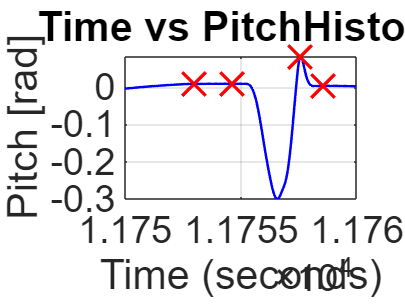

[ ~, idx1 ] = min( abs( time-11750 ) );
[ ~, idx2 ] = min( abs( time-11760 ) );

Pitch_SPPO_6 = pitch(idx1:idx2);
t_SPPO_6 = time(idx1:idx2);

figure;
plot(t_SPPO_6, Pitch_SPPO_6, 'b', 'LineWidth', 1.5)
hold on
% finds Peaks
[~,id] = findpeaks(Pitch_SPPO_6, 'MinPeakDistance', 5);
% displays peaks
plot(t_SPPO_6(id), Pitch_SPPO_6(id), 'rx',MarkerSize=20)
xlabel('Time (seconds)')
ylabel('Pitch [rad]')
title('Time vs PitchHistory')
grid on;
hold off



%SPPO_6 = periodic_response(t_SPPO_6, Pitch_SPPO_6);
%SPPO_6_lambda = non_periodic_response(t_SPPO_6, Pitch_SPPO_6);

## test 7

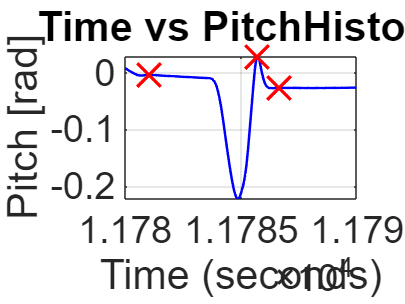

[ ~, idx1 ] = min( abs( time-11780 ) );
[ ~, idx2 ] = min( abs( time-11790 ) );

Pitch_SPPO_7 = pitch(idx1:idx2);
t_SPPO_7 = time(idx1:idx2);

figure;
plot(t_SPPO_7, Pitch_SPPO_7, 'b', 'LineWidth', 1.5)
hold on
% finds Peaks
[~,id] = findpeaks(Pitch_SPPO_7, 'MinPeakDistance', 5);
% displays peaks
plot(t_SPPO_7(id), Pitch_SPPO_7(id), 'rx',MarkerSize=20)
xlabel('Time (seconds)')
ylabel('Pitch [rad]')
title('Time vs PitchHistory')
grid on;
hold off



%SPPO_7 = periodic_response(t_SPPO_7, Pitch_SPPO_7);
%SPPO_7_lambda = non_periodic_response(t_SPPO_7, Pitch_SPPO_7);

## test 8

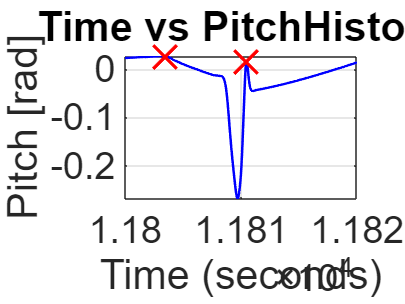

[ ~, idx1 ] = min( abs( time-11800 ) );
[ ~, idx2 ] = min( abs( time-11820 ) );

Pitch_SPPO_8 = pitch(idx1:idx2);
t_SPPO_8 = time(idx1:idx2);

figure;
plot(t_SPPO_8, Pitch_SPPO_8, 'b', 'LineWidth', 1.5)
hold on
% finds Peaks
[~,id] = findpeaks(Pitch_SPPO_8, 'MinPeakDistance', 5);
% displays peaks
plot(t_SPPO_8(id), Pitch_SPPO_8(id), 'rx',MarkerSize=20)
xlabel('Time (seconds)')
ylabel('Pitch [rad]')
title('Time vs PitchHistory')
grid on;
hold off


%SPPO_8 = periodic_response(t_SPPO_8, Pitch_SPPO_8);
%SPPO_8_lambda = non_periodic_response(t_SPPO_8, Pitch_SPPO_8);


[SPPO_1_DR, SPPO_1_dampedFreq, SPPO_1_undampedFreq, SPPO_1_eig1, SPPO_1_eig2] = getEigens(t_SPPO_1, Pitch_SPPO_1);
[SPPO_2_DR, SPPO_2_dampedFreq, SPPO_2_undampedFreq, SPPO_2_eig1, SPPO_2_eig2] = getEigens(t_SPPO_2, Pitch_SPPO_2);
[SPPO_3_DR, SPPO_3_dampedFreq, SPPO_3_undampedFreq, SPPO_3_eig1, SPPO_3_eig2] = getEigens(t_SPPO_3, Pitch_SPPO_3);
[SPPO_4_DR, SPPO_4_dampedFreq, SPPO_4_undampedFreq, SPPO_4_eig1, SPPO_4_eig2] = getEigens(t_SPPO_4, Pitch_SPPO_4);
[SPPO_5_DR, SPPO_5_dampedFreq, SPPO_5_undampedFreq, SPPO_5_eig1, SPPO_5_eig2] = getEigens(t_SPPO_5, Pitch_SPPO_5);
[SPPO_6_DR, SPPO_6_dampedFreq, SPPO_6_undampedFreq, SPPO_6_eig1, SPPO_6_eig2] = getEigens(t_SPPO_6, Pitch_SPPO_6);
[SPPO_7_DR, SPPO_7_dampedFreq, SPPO_7_undampedFreq, SPPO_7_eig1, SPPO_7_eig2] = getEigens(t_SPPO_7, Pitch_SPPO_7);
[SPPO_8_DR, SPPO_8_dampedFreq, SPPO_8_undampedFreq, SPPO_8_eig1, SPPO_8_eig2] = getEigens(t_SPPO_8, Pitch_SPPO_8);

%{
% Store values in arrays
SPPO_DR = [SPPO_1_DR, SPPO_2_DR, SPPO_3_DR, SPPO_4_DR, SPPO_5_DR, SPPO_6_DR, SPPO_7_DR, SPPO_8_DR];
SPPO_dampedFreq = [SPPO_1_dampedFreq, SPPO_2_dampedFreq, SPPO_3_dampedFreq, SPPO_4_dampedFreq, SPPO_5_dampedFreq, SPPO_6_dampedFreq, SPPO_7_dampedFreq, SPPO_8_dampedFreq];
SPPO_undampedFreq = [SPPO_1_undampedFreq, SPPO_2_undampedFreq, SPPO_3_undampedFreq, SPPO_4_undampedFreq, SPPO_5_undampedFreq, SPPO_6_undampedFreq, SPPO_7_undampedFreq, SPPO_8_undampedFreq];
SPPO_eig1 = [SPPO_1_eig1, SPPO_2_eig1, SPPO_3_eig1, SPPO_4_eig1, SPPO_5_eig1, SPPO_6_eig1, SPPO_7_eig1, SPPO_8_eig1];
SPPO_eig2 = [SPPO_1_eig2, SPPO_2_eig2, SPPO_3_eig2, SPPO_4_eig2, SPPO_5_eig2, SPPO_6_eig2, SPPO_7_eig2, SPPO_8_eig2];

% Compute averages
avg_SPPO_DR = mean(SPPO_DR);
avg_SPPO_dampedFreq = mean(SPPO_dampedFreq);
avg_SPPO_undampedFreq = mean(SPPO_undampedFreq);
avg_SPPO_eig1 = mean(SPPO_eig1);
avg_SPPO_eig2 = mean(SPPO_eig2);
%}

%Selected better tests
% Store selected SPPO values in arrays
SPPO_DR = [SPPO_3_DR, SPPO_5_DR, SPPO_6_DR, SPPO_7_DR];
SPPO_dampedFreq = [SPPO_3_dampedFreq, SPPO_5_dampedFreq, SPPO_6_dampedFreq, SPPO_7_dampedFreq];
SPPO_undampedFreq = [SPPO_3_undampedFreq, SPPO_5_undampedFreq, SPPO_6_undampedFreq, SPPO_7_undampedFreq];
SPPO_eig1 = [SPPO_3_eig1, SPPO_5_eig1, SPPO_6_eig1, SPPO_7_eig1];
SPPO_eig2 = [SPPO_3_eig2, SPPO_5_eig2, SPPO_6_eig2, SPPO_7_eig2];

% Compute means
avg_SPPO_DR = mean(SPPO_DR)

avg_SPPO_DR =    0.551704131638396


avg_SPPO_dampedFreq = mean(SPPO_dampedFreq)

avg_SPPO_dampedFreq =    4.656775135742037


avg_SPPO_undampedFreq = mean(SPPO_undampedFreq)

avg_SPPO_undampedFreq =    5.335211378146951


avg_SPPO_eig1 = mean(SPPO_eig1)

avg_SPPO_eig1 =  -4.145691440618551 + 4.656775135742037i


avg_SPPO_eig2 = mean(SPPO_eig2)

avg_SPPO_eig2 =  -4.145691440618551 - 4.656775135742037i


## Phugoid (ossilitory)

## test 1

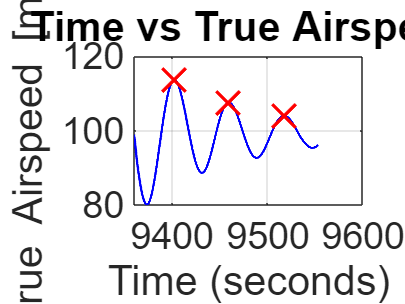

[ ~, idx1 ] = min( abs( time-9360 ) );
[ ~, idx2 ] = min( abs( time-9553 ) );

V_Phugoid_1 = vInd_kias(idx1:idx2);
t_Phugoid_1 = time(idx1:idx2);

figure;
plot(t_Phugoid_1, V_Phugoid_1, 'b', 'LineWidth', 1.5)
hold on
% finds Peaks
[~,id] = findpeaks(V_Phugoid_1, 'MinPeakDistance', 5);
% displays peaks
plot(t_Phugoid_1(id), V_Phugoid_1(id), 'rx',MarkerSize=20)
xlabel('Time (seconds)')
ylabel('True Airspeed [ms^-1]')
title('Time vs True Airspeed')
grid on;
hold off



%Phugoid_1 = periodic_response(t_Phugoid_1, V_Phugoid_1);;
% Phugoid_1_lambda = non_periodic_response(t_Phugoid_1, V_Phugoid_1);

## test 2

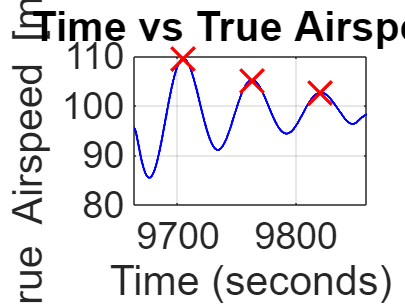

[ ~, idx1 ] = min( abs( time-9663 ) );
[ ~, idx2 ] = min( abs( time-9860 ) );

V_Phugoid_2 = vInd_kias(idx1:idx2);
t_Phugoid_2 = time(idx1:idx2);

figure;
plot(t_Phugoid_2, V_Phugoid_2, 'b', 'LineWidth', 1.5)
hold on
% finds Peaks
[~,id] = findpeaks(V_Phugoid_2, 'MinPeakDistance', 5);
% displays peaks
plot(t_Phugoid_2(id), V_Phugoid_2(id), 'rx',MarkerSize=20)
xlabel('Time (seconds)')
ylabel('True Airspeed [ms^-1]')
title('Time vs True Airspeed')
grid on;
hold off



%Phugoid_2 = periodic_response(t_Phugoid_2, V_Phugoid_2);
% Phugoid_2_lambda = non_periodic_response(t_Phugoid_2, V_Phugoid_2);

% define data series
[Phugoid_1_DR, Phugoid_1_dampedFreq, Phugoid_1_undampedFreq, Phugoid_1_eig1, Phugoid_1_eig2] = getEigens(t_Phugoid_1, V_Phugoid_1);
[Phugoid_2_DR, Phugoid_2_dampedFreq, Phugoid_2_undampedFreq, Phugoid_2_eig1, Phugoid_2_eig2] = getEigens(t_Phugoid_2, V_Phugoid_2);


Phugoid_DR = [Phugoid_1_DR, Phugoid_2_DR];
Phugoid_dampedFreq = [Phugoid_1_dampedFreq, Phugoid_2_dampedFreq];
Phugoid_undampedFreq = [Phugoid_1_undampedFreq, Phugoid_2_undampedFreq];
Phugoid_eig1 = [Phugoid_1_eig1, Phugoid_2_eig1];
Phugoid_eig2 = [Phugoid_1_eig2, Phugoid_2_eig2];

% Compute means
avg_Phugoid_DR = mean(Phugoid_DR)

avg_Phugoid_DR =    0.479716317255477


avg_Phugoid_dampedFreq = mean(Phugoid_dampedFreq)

avg_Phugoid_dampedFreq =    0.108673122278052


avg_Phugoid_undampedFreq = mean(Phugoid_undampedFreq)

avg_Phugoid_undampedFreq =    0.123869747792724


avg_Phugoid_eig1 = mean(Phugoid_eig1)

avg_Phugoid_eig1 =  -0.059455698191370 + 0.108673122278052i


avg_Phugoid_eig2 = mean(Phugoid_eig2)

avg_Phugoid_eig2 =  -0.059455698191370 - 0.108673122278052i


## Roll Test

## test 1

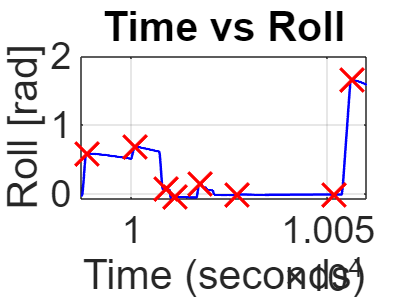

[ ~, idx1 ] = min( abs( time-9987 ) );
[ ~, idx2 ] = min( abs( time-10060 ) );

Roll_Roll_Subsidance_1 = roll(idx1:idx2);
t_Roll_Subsidance_1 = time(idx1:idx2);

figure;
plot(t_Roll_Subsidance_1, Roll_Roll_Subsidance_1, 'b', 'LineWidth', 1.5)
hold on
% finds Peaks
[~,id] = findpeaks(Roll_Roll_Subsidance_1, 'MinPeakDistance', 5);
% displays peaks
plot(t_Roll_Subsidance_1(id), Roll_Roll_Subsidance_1(id), 'rx',MarkerSize=20)
xlabel('Time (seconds)')
ylabel('Roll [rad]')
title('Time vs Roll')
grid on;
hold off




%Roll_Subsidance_1 = periodic_response(t_Roll_Subsidance_1, Roll_Roll_Subsidance_1);
%Roll_Subsidance_1_lambda = non_periodic_response(t_Roll_Subsidance_1, Roll_Roll_Subsidance_1);


## test 2

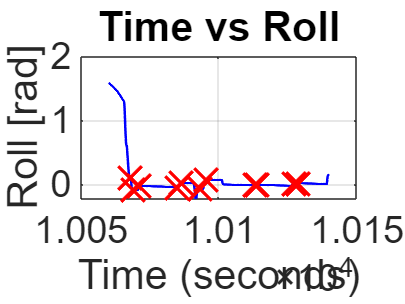

[ ~, idx1 ] = min( abs( time-10060 ) );
[ ~, idx2 ] = min( abs( time-10140 ) );

Roll_Roll_Subsidance_2 = roll(idx1:idx2);
t_Roll_Subsidance_2 = time(idx1:idx2);

figure;
plot(t_Roll_Subsidance_2, Roll_Roll_Subsidance_2, 'b', 'LineWidth', 1.5)
hold on
% finds Peaks
[~,id] = findpeaks(Roll_Roll_Subsidance_2, 'MinPeakDistance', 5);
% displays peaks
plot(t_Roll_Subsidance_2(id), Roll_Roll_Subsidance_2(id), 'rx',MarkerSize=20)
xlabel('Time (seconds)')
ylabel('Roll [rad]')
title('Time vs Roll')
grid on;
hold off



%Roll_Subsidance_2 = periodic_response(t_Roll_Subsidance_2, Roll_Roll_Subsidance_2);

%Roll_Subsidance_2_lambda = non_periodic_response(t_Roll_Subsidance_2, Roll_Roll_Subsidance_2);

## test 3

%[ ~, idx1 ] = min( abs( time-10141 ) );
%[ ~, idx2 ] = min( abs( time-10173 ) );

Roll_Roll_Subsidance_3 = roll(idx1:idx2);
t_Roll_Subsidance_3 = time(idx1:idx2);

figure;
plot(t_Roll_Subsidance_3, Roll_Roll_Subsidance_3, 'b', 'LineWidth', 1.5)
hold on
% finds Peaks
[~,id] = findpeaks(Roll_Roll_Subsidance_3, 'MinPeakDistance', 5);
% displays peaks
plot(t_Roll_Subsidance_3(id), Roll_Roll_Subsidance_3(id), 'rx',MarkerSize=20)
xlabel('Time (seconds)')
ylabel('Roll [rad]')
title('Time vs Roll')
grid on;
hold off

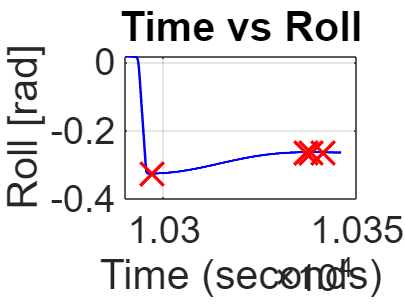



%Roll_Subsidance_3 = periodic_response(t_Roll_Subsidance_3, Roll_Roll_Subsidance_3);

%Roll_Subsidance_3_lambda = non_periodic_response(t_Roll_Subsidance_3, Roll_Roll_Subsidance_3);

 %% test 4
 [ ~, idx1 ] = min( abs( time-10290 ) );
 [ ~, idx2 ] = min( abs( time-10370 ) );

 Roll_Roll_Subsidance_4 = roll(idx1:idx2);
 t_Roll_Subsidance_4 = time(idx1:idx2);

 figure;
 plot(t_Roll_Subsidance_4, Roll_Roll_Subsidance_4, 'b', 'LineWidth', 1.5)
 hold on
 % finds Peaks
 [~,id] = findpeaks(Roll_Roll_Subsidance_4, 'MinPeakDistance', 5);
 % displays peaks
 plot(t_Roll_Subsidance_4(id), Roll_Roll_Subsidance_4(id), 'rx',MarkerSize=20)
 xlabel('Time (seconds)')
 ylabel('Roll [rad]')
 title('Time vs Roll')
 grid on;
 hold off



% Roll_Subsidance_4 = periodic_response(t_Roll_Subsidance_4, Roll_Roll_Subsidance_4);
%
% Roll_Subsidance_4_lambda = non_periodic_response(t_Roll_Subsidance_4, Roll_Roll_Subsidance_4);
%


%[RS1_DR,RS1_DF,RS1_UF,RS1_Eig1,RS1_Eig2] = getEigens(t_Roll_Subsidance_1, Roll_Roll_Subsidance_1);
%[RS2_DR,RS2_DF,RS2_UF,RS2_Eig1,RS2_Eig2] = getEigens(t_Roll_Subsidance_2, Roll_Roll_Subsidance_2);
%[RS4_DR,RS4_DF,RS4_UF,RS4_Eig1,RS4_Eig2] = getEigens(t_Roll_Subsidance_4, Roll_Roll_Subsidance_4);

%RS_Eig = mean(real([RS1_Eig2,RS2_Eig2,RS4_Eig2]))

%RS1Eig = non_periodic_response(t_Roll_Subsidance_1, Roll_Roll_Subsidance_1);
RS2Eig = non_periodic_response(t_Roll_Subsidance_2, Roll_Roll_Subsidance_2);
RS3Eig = non_periodic_response(t_Roll_Subsidance_3, Roll_Roll_Subsidance_3);
RS4Eig = non_periodic_response(t_Roll_Subsidance_4, Roll_Roll_Subsidance_4);

RS4Eig = mean([RS2Eig, RS3Eig,RS4Eig])

RS4Eig =   -0.500229187337394







% % define data series

## Dutch Roll (ossilitory)

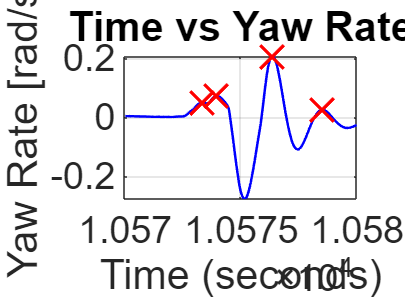

% define data series
%Test 1
 [ ~, idx1 ] = min( abs( time-10570 ) );
 [ ~, idx2 ] = min( abs( time-10580 ) );

 Yaw_DutchRoll_1 = r(idx1:idx2);
 t_DutchRoll_1 = time(idx1:idx2);

  figure;
 plot(t_DutchRoll_1, Yaw_DutchRoll_1, 'b', 'LineWidth', 1.5)
 hold on
 % finds Peaks
 [~,id] = findpeaks(Yaw_DutchRoll_1, 'MinPeakDistance', 5);
 % displays peaks
 plot(t_DutchRoll_1(id), Yaw_DutchRoll_1(id), 'rx',MarkerSize=20)
 xlabel('Time (seconds)')
 ylabel('Yaw Rate [rad/s]')
 title('Time vs Yaw Rate')
 grid on;
 hold off

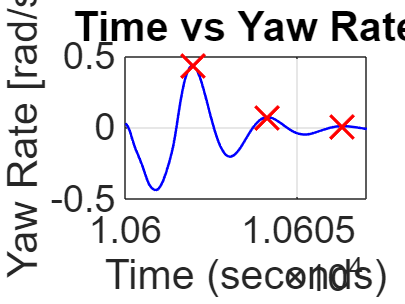


 [ ~, idx1 ] = min( abs( time-10600 ) );
 [ ~, idx2 ] = min( abs( time-10607 ) );

 Yaw_DutchRoll_2 = r(idx1:idx2);
 t_DutchRoll_2 = time(idx1:idx2);

  figure;
 plot(t_DutchRoll_2, Yaw_DutchRoll_2, 'b', 'LineWidth', 1.5)
 hold on
 % finds Peaks
 [~,id] = findpeaks(Yaw_DutchRoll_2, 'MinPeakDistance', 5);
 % displays peaks
 plot(t_DutchRoll_2(id), Yaw_DutchRoll_2(id), 'rx',MarkerSize=20)
 xlabel('Time (seconds)')
 ylabel('Yaw Rate [rad/s]')
 title('Time vs Yaw Rate')
 grid on;
 hold off

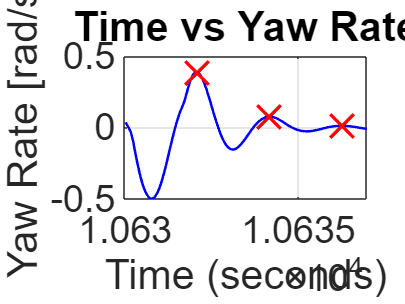


  [ ~, idx1 ] = min( abs( time-10630 ) );
 [ ~, idx2 ] = min( abs( time-10637 ) );

 Yaw_DutchRoll_3 = r(idx1:idx2);
 t_DutchRoll_3= time(idx1:idx2);

  figure;
 plot(t_DutchRoll_3, Yaw_DutchRoll_3, 'b', 'LineWidth', 1.5)
 hold on
 % finds Peaks
 [~,id] = findpeaks(Yaw_DutchRoll_3, 'MinPeakDistance', 5);
 % displays peaks
 plot(t_DutchRoll_3(id), Yaw_DutchRoll_3(id), 'rx',MarkerSize=20)
 xlabel('Time (seconds)')
 ylabel('Yaw Rate [rad/s]')
 title('Time vs Yaw Rate')
 grid on;
 hold off

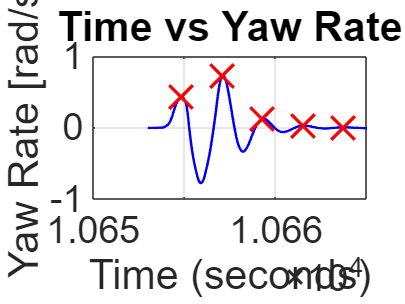


  [ ~, idx1 ] = min( abs( time-10653 ) );
 [ ~, idx2 ] = min( abs( time-10665 ) );

 Yaw_DutchRoll_4 = r(idx1:idx2);
 t_DutchRoll_4 = time(idx1:idx2);


  figure;
 plot(t_DutchRoll_4, Yaw_DutchRoll_4, 'b', 'LineWidth', 1.5)
 hold on
 % finds Peaks
 [~,id] = findpeaks(Yaw_DutchRoll_4, 'MinPeakDistance', 5);
 % displays peaks
 plot(t_DutchRoll_4(id), Yaw_DutchRoll_4(id), 'rx',MarkerSize=20)
 xlabel('Time (seconds)')
 ylabel('Yaw Rate [rad/s]')
 title('Time vs Yaw Rate')
 grid on;
 hold off



[DutchRoll_1_DR, DutchRoll_1_dampedFreq, DutchRoll_1_undampedFreq, DutchRoll_1_eig1, DutchRoll_1_eig2] = getEigens(t_DutchRoll_1, Yaw_DutchRoll_1);
[DutchRoll_2_DR, DutchRoll_2_dampedFreq, DutchRoll_2_undampedFreq, DutchRoll_2_eig1, DutchRoll_2_eig2] = getEigens(t_DutchRoll_2, Yaw_DutchRoll_2);
[DutchRoll_3_DR, DutchRoll_3_dampedFreq, DutchRoll_3_undampedFreq, DutchRoll_3_eig1, DutchRoll_3_eig2] = getEigens(t_DutchRoll_3, Yaw_DutchRoll_3);
[DutchRoll_4_DR, DutchRoll_4_dampedFreq, DutchRoll_4_undampedFreq, DutchRoll_4_eig1, DutchRoll_4_eig2] = getEigens(t_DutchRoll_4, Yaw_DutchRoll_4);


% Store values in arrays
DutchRoll_DR = [DutchRoll_1_DR, DutchRoll_2_DR, DutchRoll_3_DR, DutchRoll_4_DR];
DutchRoll_dampedFreq = [DutchRoll_1_dampedFreq, DutchRoll_2_dampedFreq, DutchRoll_3_dampedFreq, DutchRoll_4_dampedFreq];
DutchRoll_undampedFreq = [DutchRoll_1_undampedFreq, DutchRoll_2_undampedFreq, DutchRoll_3_undampedFreq, DutchRoll_4_undampedFreq];
DutchRoll_eig1 = [DutchRoll_1_eig1, DutchRoll_2_eig1, DutchRoll_3_eig1, DutchRoll_4_eig1];
DutchRoll_eig2 = [DutchRoll_1_eig2, DutchRoll_2_eig2, DutchRoll_3_eig2, DutchRoll_4_eig2];

% Compute averages
avg_DutchRoll_DR = mean(DutchRoll_DR)

avg_DutchRoll_DR =    0.476731365040236


avg_DutchRoll_dampedFreq = mean(DutchRoll_dampedFreq)

avg_DutchRoll_dampedFreq =    3.485614993185957


avg_DutchRoll_undampedFreq = mean(DutchRoll_undampedFreq)

avg_DutchRoll_undampedFreq =    3.944818149500001


avg_DutchRoll_eig1 = mean(DutchRoll_eig1)

avg_DutchRoll_eig1 =  -1.972401186763360 + 3.485614993185957i


avg_DutchRoll_eig2 = mean(DutchRoll_eig2)

avg_DutchRoll_eig2 =  -1.972401186763360 - 3.485614993185957i


## Spiral Mode (non-ossilitory)

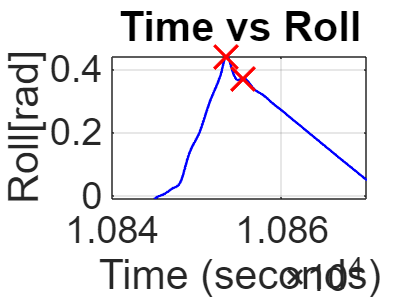

% define data series
[ ~, idx1 ] = min( abs( time-10845 ) );
 [ ~, idx2 ] = min( abs( time-10870 ) );
 Roll_Spiral_1 = roll(idx1:idx2);
 t_Spiral_1 = time(idx1:idx2);

  figure;
 plot(t_Spiral_1, Roll_Spiral_1, 'b', 'LineWidth', 1.5)
 hold on
 % finds Peaks
 [~,id] = findpeaks(Roll_Spiral_1, 'MinPeakDistance', 5);
 % displays peaks
 plot(t_Spiral_1(id), Roll_Spiral_1(id), 'rx',MarkerSize=20)
 xlabel('Time (seconds)')
 ylabel('Roll[rad]')
 title('Time vs Roll')
 grid on;
 hold off

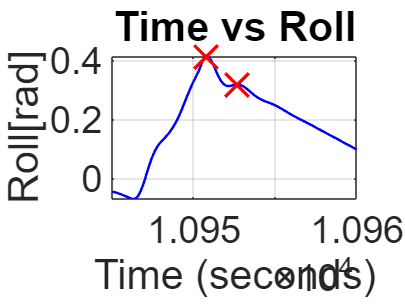


[ ~, idx1 ] = min( abs( time-10945 ) );
 [ ~, idx2 ] = min( abs( time-10960 ) );
 Roll_Spiral_2 = roll(idx1:idx2);
 t_Spiral_2 = time(idx1:idx2);

  figure;
 plot(t_Spiral_2, Roll_Spiral_2, 'b', 'LineWidth', 1.5)
 hold on
 % finds Peaks
 [~,id] = findpeaks(Roll_Spiral_2, 'MinPeakDistance', 5);
 % displays peaks
 plot(t_Spiral_2(id), Roll_Spiral_2(id), 'rx',MarkerSize=20)
 xlabel('Time (seconds)')
 ylabel('Roll[rad]')
 title('Time vs Roll')
 grid on;
 hold off

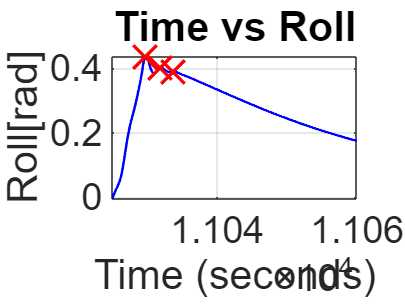



 [ ~, idx1 ] = min( abs( time-11025 ) );
 [ ~, idx2 ] = min( abs( time-11060 ) );
 Roll_Spiral_3 = roll(idx1:idx2);
 t_Spiral_3 = time(idx1:idx2);

   figure;
 plot(t_Spiral_3, Roll_Spiral_3, 'b', 'LineWidth', 1.5)
 hold on
 % finds Peaks
 [~,id] = findpeaks(Roll_Spiral_3, 'MinPeakDistance', 5);
 % displays peaks
 plot(t_Spiral_3(id), Roll_Spiral_3(id), 'rx',MarkerSize=20)
xlabel('Time (seconds)')
 ylabel('Roll[rad]')
 title('Time vs Roll')
 grid on;
 hold off


Spiral1Eig = non_periodic_response(t_Spiral_1, Roll_Spiral_1);
Spiral2Eig = non_periodic_response(t_Spiral_2, Roll_Spiral_2);
Spiral3Eig = non_periodic_response(t_Spiral_3, Roll_Spiral_3);

avg_spiral_eig = mean([Spiral1Eig, Spiral2Eig, Spiral3Eig])

avg_spiral_eig =   -0.085820073268124


## Periodic Response Function

function [omega_damped, damping_ratio, omega_natural, lambda_1, lambda_2] = periodic_response(time, amplitude)

% [pks,locs] = findpeaks(amplitude, 'MinPeakDistance', 20);


[pks, locs] = findpeaks(amplitude);

% findpeaks(amplitude);
period = zeros( 1, length(locs) - 1 );
delta = zeros( 1, length(locs) - 1 );

for i = 1:( length(locs) - 1 )
    %calculates periods between peaks
    period(i) = time( locs(i+1) ) - time( locs(i) );

    %clacluates logrithmic dectremnt
    delta(i) = log( pks(i) / pks(i+1));
end

% delta = ln( amplitude(locs) / parameters(locs) );

damping_ratio = mean(1 ./ sqrt( 1 + ( (2 * pi) ./ delta ) ));

omega_damped = mean(2 * pi ./ period);

omega_natural = mean(omega_damped ./ sqrt(1 - damping_ratio .^ 2));


%calculates the eigenvalues of the state
lambda_1 = ((-1) * omega_damped * damping_ratio)/(sqrt(1-damping_ratio^2)) - omega_damped*1i;
lambda_2 = ((-1) * omega_damped * damping_ratio)/(sqrt(1-damping_ratio^2)) + omega_damped*1i;

end

## Non-Periodic Response

function [mean_lambda, lambda] = non_periodic_response(time, amplitude)

[pks,locs] = findpeaks(amplitude);

period = zeros( 1, length(locs) - 1 );

lambda = zeros( 1, length(locs) - 1 );

for i = 1:( length(locs) - 1 )
    %calculates periods between peaks
    period(i) = time( locs(i+1) ) - time( locs(i) );

    %calculates the eigenvalues of the state
    lambda(i) = (1 / period(i)) .* -abs(log(pks(i+1)./(pks(i))));

    % mean_lambda = mean(lambda);
end
mean_lambda = mean(lambda);

end

## FFT for finding frequency of response

function [dominant_frequency] = calculateAverageFrequency(amplitude)

% Load the data from the file
% Extract the time column (first column)
time = amplitude(:, 1);

% Determine the number of vessels from the data
num_vessels = (size(amplitude, 2) - 1) / 3; % Assuming y, v, h per vessel

% Initialize a variable to store the sum of dominant frequencies
dominant_frequency = zeros(num_vessels,1);

% Loop through each vessel to calculate its dominant frequency
for i = 1:num_vessels

    % Extract displacement data for the vessel
    displacement = amplitude(:, 3 * i - 1);

    % Perform Fourier Transform on the displacement data
    Y = fft(displacement);
    L = length(time);

    % Compute the two-sided spectrum and then the single-sided spectrum
    P2 = abs(Y / L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2 * P1(2:end-1);

    % Define the frequency domain
    f = (0:(L/2)) / max(time);

    % Find the frequency corresponding to the maximum amplitude
    [~, max_idx] = max(P1);
    dominant_frequency(i) = f(max_idx);

    % fprintf('The frequency of vessel %.1f is %.4f Hz\n',i ,dominant_frequency);
end
% Calculate the average frequency
% Display the result
end

%%%Find Eigenvectors Oscilitory %%%
function [dampingRatio, dampedOmega, undampedOmega,eig1, eig2] = getEigens(time, amplitude)
    [~,id] = findpeaks(amplitude);

    did = zeros(1,size(id,1) -1);
    i = 1;
    while i <= length(did)
        did(i) = time(id(i+1)) - time(id(i));
        i = i + 1;
    end
    
    dampedOmega = (2*pi)./did;
    
    dAmp = zeros(1,size(id,1) -1);
    i = 1;
    while i <=length(dAmp)
        dAmp(i)= abs(log(amplitude(id(i+1)) - amplitude(id(i))));
        i = i + 1;
    end
    
    dampingRatio = 1./sqrt(1+(2*pi./dAmp).^2);
    
    real = mean(-(dampedOmega .* dampingRatio)./sqrt(1-dampingRatio.^2));
    
    img = mean(dampedOmega);
    
    eig1 = complex(real,img);
    eig2 = complex(real,-img);
    undampedOmega = mean(dampedOmega/(sqrt(1-dampingRatio.^2)));
    dampingRatio = mean(dampingRatio);
    dampedOmega = mean(dampedOmega);
end

function eig = getEigen(time,amplitude)
    id = floor(linspace(1,size(time,1)));
    
    lambda = zeros(size(id,2) - 1,1);

    i = 1;
    while i < size(lambda,2)
        lambda(i) =log(amplitude(id(i+1))/amplitude(id(i)))/(time(id(i+1)) - id(i));
    end
    eig = mean(lambda);
end